clear all
f = @(x1, x2) x1 + 2*x2;
g = @(x1, x2) (1/4)*x1.^2 + x2.^2 - 1;

% quadratic 
Q = @(x1, x2, mu) f(x1, x2) + (mu/2)*(max(0,g(x1, x2)).^2);

% L1
% not easy in MATLAB then skip
%Q  = arrayfun(@(x1, x2, mu) f(x1, x2) + mu*norm(max(0,g(x1,x2)),1), x1, x2);

gcb = @(x) sqrt(-(1/4)*x.^2 + 1);
f1 = @(x) x(1) + 2*x(2);
g1 = @(x) (1/4)*x(1).^2 + x(2).^2 - 1;

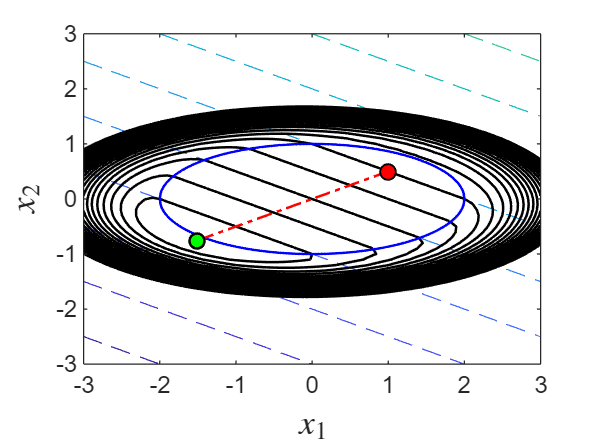

clf; clc;

x1 = -3:0.1:3; x2 = -3:0.1:3;
x1s = -2:0.01:2;
[X1, X2] = meshgrid(x1, x2);

stepsize = [0, 3, 4, 20];
k = stepsize(4);
xs_P = zeros(k, 2);

% Initail values of all variables
x0 = [1, 0.5];
x01 = x0;
xs_P(1,:) = x0;
rho = 1; mu1 = 10;
xs_P(1,:) = x0;

% Contour plot of the objective function 
contour(X1, X2, f(X1, X2), LineStyle='--');
hold on
levels = -20:1:20;
contour(X1, X2, Q(X1, X2, mu1), [levels], color='k', linewidth=1);
plot(x1s, gcb(x1s), linewidth=1, color='b');
plot(x1s, -gcb(x1s), linewidth=1, color='b');

xlabel("$x_1$",'Interpreter','latex','FontSize',14);
ylabel("$x_2$",'Interpreter','latex','FontSize',14);

for ii = 1:k    
    obj = @(x) f1(x)  + (mu1/2)*(max(0,g1(x)).^2);
    %obj = @(x) f1(x)  + mu1*norm(max(0,g1(x)),1);
    options = optimoptions(@fminunc,'Display','none');
    x = fminunc(obj, x0, options);

    xs_P(ii+1,:) = x;
    mu1 = rho*mu1;
    x0 = x;
end

plot(xs_P(1:10,1), xs_P(1:10,2),'ro-.', 'MarkerFaceColor','g', ...
    'linewidth',1, 'MarkerEdgeColor','k')
plot(x01(1,1), x01(1,2),'ro','MarkerFaceColor','r','MarkerEdgeColor','k' )

hold off